# BootstrapNorm

Illustrates bootstrapping by resampling to find confidence intervals.

Author: D. Carlsmith

clearvars;delete(findall(0,'Type','figure'))

Uncomment the following to reset the random number generation in running this script for reproducibility.

%rng('default')  % For reproducibility

Generate Ndata=100 samples of the normal distribution N(5,1) (mean 5, std=1).

Ndata=100;truemean=5;truesigma=1;
y=normrnd(truemean,truesigma,[1 Ndata]);
%histogram(y)

Resample Nresample times, estimating means and standard deviations.

Nresample=1000;
[stats, samples] = bootstrp(Nresample,@(x)[mean(x) std(x)],y);

Scatter plot the estimates of mean and standard deviation.

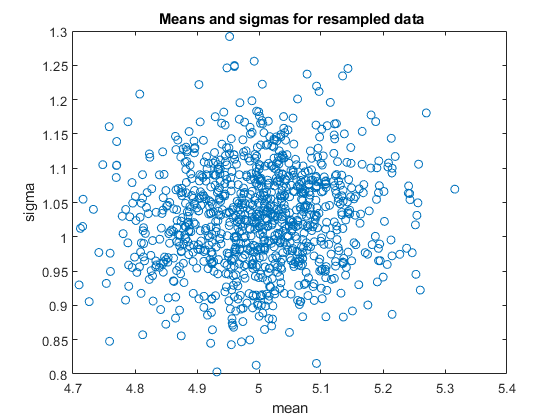

figure
plot(stats(:,1),stats(:,2),'o');xlabel('mean');ylabel('sigma')
title(' Means and sigmas for resampled data')

Fit distribution of means to a normal distribution. The std of this should be sigma/Ndata^(1/2).

[muHat,sigmaHat,muCI,sigmaCI] = normfit(stats(:,1))

muHat = 4.9971

sigmaHat = 0.1027

muCI =     4.9908
    5.0035


sigmaCI =     0.0984
    0.1074


expect = truesigma/(Ndata)^(1/2)

expect = 0.1000

% y(samples(i,j)) for i= [1 Ndata], j=[1 Nresample] = resample data.

Histogram all resamples treated as one big sample.

figure
h1=histogram(y(samples),'Normalization','pdf','BinWidth',2*truemean/100);
hold on

Compare to original - the values should agree closely.

h2=histogram(y,'Normalization','pdf','BinWidth',2*truemean/100);
xlabel('x');ylabel('Probability density');
legend('All resamples','Sample')

Show a few resamples, pausing between displays.

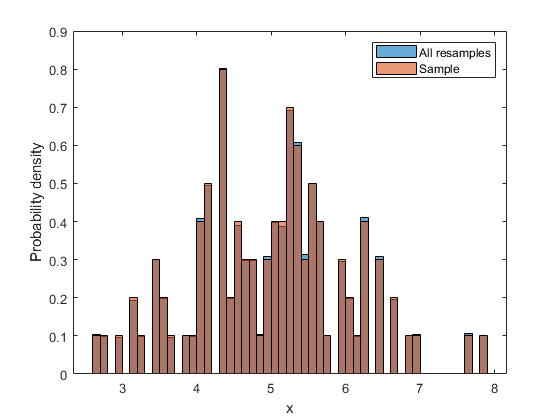

hold off

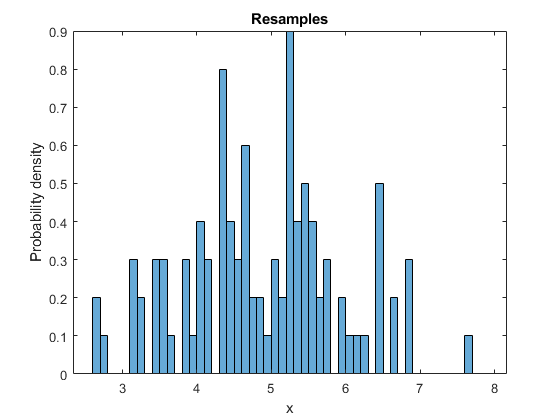

edges=h2.BinEdges;% use the same histogram bins
figure
for j=1:50
    h3=histogram(y( samples(:,j) ) ,'BinEdges', edges, ...
        'Normalization','pdf');
    pause(.5)
    title('Resamples');xlabel('x');ylabel('Probability density')
end